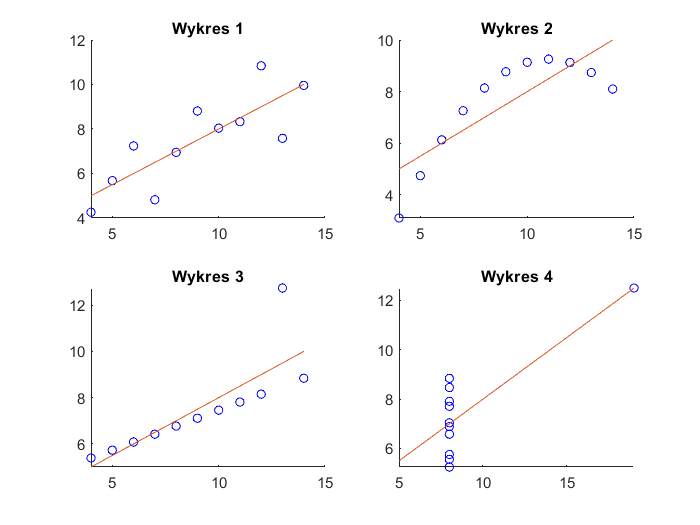

fullMatFileName = fullfile('data.mat');
if ~exist(fullMatFileName, 'file')
  message = sprintf('%s does not exist', fullMatFileName);
  uiwait(warndlg(message));
else
  s = load(fullMatFileName);
end
X1=s.data(1:11);
Y1=s.data(12:22);
X2=s.data(23:33);
Y2=s.data(34:44);
X3=s.data(45:55);
Y3=s.data(56:66);
X4=s.data(67:77);
Y4=s.data(78:88);

mean(X1);
var(X1);
mean(X2);
var(X2);
mean(X3);
var(X3);
mean(X4);
var(X4);
mean(Y1);
var(Y1);
mean(Y2);
var(Y2);
mean(Y3);
var(Y3);
mean(Y4);
var(Y4);

cor1=corrcoef(X1,Y1);
cor2=corrcoef(X2,Y2);
cor3=corrcoef(X3,Y3);
cor4=corrcoef(X4,Y4);

cor1(2:2,1:1);
cor2(2:2,1:1);
cor3(2:2,1:1);
cor4(2:2,1:1);


figure(1);

subplot(2, 2, 1);
scatter(X1, Y1, 25, 'b', 'o');
hold on;
P = polyfit(X1, Y1, 1);
yfit = polyval(P, X1);
plot(X1, yfit);
%eqn = "Linear: y = " + string(P(1)) + "x + " + string(P(2));
%text(min(X1), max(Y1), eqn, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
hold off;
title('Wykres 1');

subplot(2, 2, 2);
scatter(X2, Y2, 25, 'b', 'o');
hold on;
P = polyfit(X2, Y2, 1);
yfit = polyval(P, X2);
plot(X2, yfit);
%eqn = "Linear: y = " + string(P(1)) + "x + " + string(P(2));
%text(min(X2), max(Y2), eqn, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
hold off;
title('Wykres 2');

subplot(2, 2, 3);
scatter(X3, Y3, 25, 'b', 'o');
hold on;
P = polyfit(X3, Y3, 1);
yfit = polyval(P, X3);
plot(X3, yfit);
%eqn = "Linear: y = " + string(P(1)) + "x + " + string(P(2));
%text(min(X3), max(Y3), eqn, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
hold off;
title('Wykres 3');

subplot(2, 2, 4);
scatter(X4, Y4, 25, 'b', 'o');
hold on;
x_range = 5:20; 
yfit = polyval(P, x_range);
plot(x_range, yfit);
%eqn = "Linear: y = " + string(P(1)) + "x + " + string(P(2));
%text(min(x_range), max(Y4), eqn, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
xlim([min(x_range) max(X4)]);
hold off;
title('Wykres 4');